# PRÁCTICA 1 - DETECCIÓN AUTOMÁTICA DE EQUIPOS DE FUTBOL EN IMÁGENES

#### Tips y cosas:

- 30% de la Nota de Laboratorio

- Hay que probar RGB y HSV a ver que es mejor

- Mirar bien los bins de los histogramas para hacer la comparación

- Normalizar para hacer el problema más tratable

- Normalizar HSV => Eliminar V

- Tantos histogramas para el modelo como hagan falta: 2 o 3 => Para variar las posibilidades de histograma: Mucho blaugrana, poco blaugrana, etc

- Probar a hacer recortes aleatorios, toda la imagen, etc...

- Para la comparación la distribución de color tiene que ser significativamente igual.

- Se puede utilizar automaización de detección de formas de camiseta.

- Comparación de histogramas (de vecindad): Mínimos Cuadrados (post filtrado gaussiano), Chi-Square.

- Histograma 3-dimensional (con tripletas, no histograma 3D)

- Reducir los colores: Cada 4, 8 16 niveles de rojo, azul, verde => Para que coincidan los histogramas.

- Se puede aplicar normalización de color => Obtenemos una aplicación más tolerante a cambios de color y nos podemos cargar una componente => Histograma bidimensional.

## Global Definitions

### Barça Model

bins = 128;

bcnImageModel1 = imagePreProcessingRGB(imread('./soccer/barcelona/41.jpg'));
bcnImageModel2 = imagePreProcessingRGB(imread('./soccer/barcelona/42.jpg'));
bcnImageModel3 = imagePreProcessingRGB(imread('./soccer/barcelona/43.jpg'));

histModelRGB1 = histogramRGB(bcnImageModel1, bins);
histModelRGB2 = histogramRGB(bcnImageModel2, bins);
histModelRGB3 = histogramRGB(bcnImageModel3, bins);

histModelHSV1 = histogramHSV(bcnImageModel1, bins);
histModelHSV2 = histogramHSV(bcnImageModel2, bins);
histModelHSV3 = histogramHSV(bcnImageModel3, bins);

% 3 modelos a, b, c => a*0.2 + b*0.4 + c*0.6
bcnModelRGB = {{histModelRGB1, histModelRGB2, histModelRGB2}, {0.2, 0.4, 0.6}};
bcnModelHSV = {{histModelHSV1, histModelHSV2, histModelHSV3}, {0.2, 0.4, 0.6}};

% dist_X < bcn__Threshold => True (is Barça)
bcnRGBThreshold = 0.1; % TO DO
bcnHSVThreshold = 0.1; % TO DO

## Experiments

imagesMilan = getTeamImages('./soccer/acmilan/', '*.jpg', false);
imagesChelsea = getTeamImages('./soccer/chelsea/', '*.jpg', false);
imagesJuventus = getTeamImages('./soccer/juventus/', '*.jpg', false);
imagesLiverpool = getTeamImages('./soccer/liverpool/', '*.jpg', false);
imagesMadrid = getTeamImages('./soccer/madrid/', '*.jpg', false);
imagesPSV = getTeamImages('./soccer/psv/', '*.jpg', false);
imagesBarcelona = getTeamImages('./soccer/barcelona/', '*.jpg', false);

bins = 128
bcnRGBThreshold = calculateThreshold(bcnModelHSV, imagesBarcelona, imagesMilan, 1, bins, @compareEuclideanDistance)

% ---------------------------------------- EXPERIMENTS AREA ----------------------------------------


bins = 128

histogramsTeam = 1×43 cell array
    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}


histogramsNotTeam = 1×40 cell array
    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}    {128×128 double}


resultsTeam = 	1.0e+-5 *

    0.0234    0.0106    0.0198    0.0115    0.0121    0.0152    0.0245    0.1396    0.0143    0.0132    0.0150    0.2427    0.0149    0.0392    0.0186    0.0093    0.0115    0.0195    0.0118    0.0106    0.0212    0.0408    0.0164    0.0157    0.0223    0.0511    0.0108    0.0099    0.0239    0.0094    0.0119    0.0152    0.0113    0.0144    0.0357    0.0125    0.0187    0.0221    0.0159    0.0092    0.0138    0.0092    0.0080


resultsNotTeam = 	1.0e+-6 *

    0.1215    0.1504    0.2446    0.1259    0.2838    0.1108    0.1944    0.2026    0.1361    0.1127    0.1229    0.2638    0.5642    0.2061    0.6119    0.2460    0.3501    0.2162    0.6080    0.2016    0.2526    0.2625    0.0937    0.2285    0.1295    0.3424    0.2180    0.1984    0.1225    0.2266    0.4452    0.1001    0.1445    0.1187    0.1384    0.1252    0.3057    0.1572    0.1360    0.1935


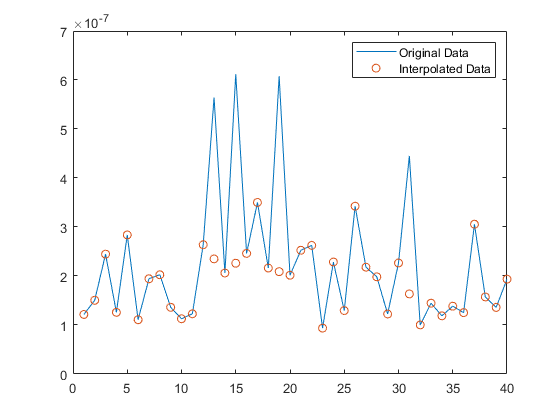

t = 2.2520e-07

bcnRGBThreshold = 2.2520e-07

% Example of use of the experiments function:

experiments(imagesMilan, bins, containers.Map({'models', 'threshold'}, {bcnModelRGB, bcnRGBThreshold}), @compareEuclideanDistance);
% Note that we should choose just imagesMilan, distance function and the color model of bcnModelRGB and bcnRGBThreshold.
% All else depend on the model parametrization.



Results table:


results = 1×40 cell array
    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}


Positive cases:
Image 1: 1.1495e-07
Image 2: 1.4654e-07
Image 4: 1.2078e-07
Image 6: 9.931e-08
Image 7: 1.8991e-07
Image 8: 1.9704e-07
Image 9: 1.3198e-07
Image 10: 1.1273e-07
Image 11: 1.2132e-07
Image 14: 2.0331e-07
Image 18: 2.0563e-07
Image 20: 1.9437e-07
Image 23: 9.6479e-08
Image 24: 2.174e-07
Image 25: 1.2478e-07
Image 27: 2.1228e-07
Image 28: 1.9307e-07
Image 29: 1.1706e-07
Image 30: 2.1886e-07
Image 32: 9.1438e-08
Image 33: 1.3854e-07
Image 34: 1.1317e-07
Image 35: 1.3261e-07
Image 36: 1.2229e-07
Image 38: 1.5264e-07
Image 39: 1.2724e-07
Image 40: 1.8772e-07
Total positive cases: 27
Negative cases:
Image 3: 2.3897e-07
Image 5: 2.7807e-07
Image 12: 2.6169e-07
Image 13: 5.5987e-07
Image 15: 6.0657e-07
Image 16: 2.3656e-07
Image 17: 3.4463e-07
Image 19: 6.0265e-07
Image 21: 2.483e-07
Image 22: 2.5783e-07
Image 26: 3.3114e-07
Image 31: 4.4208e-07
Image 37: 3.0148e-07
Total negative cases: 13


**Function to calculate the optimal threshold to diferentiate between two classes, images of the team, and images that aren't of that team **

- teamModels: model to which the distance is calculated

- imagesTeam: train set of images of the team to calculate the threshold

- imagesNotTeam: train set of images not of the team to calculate the threshold

- rgbOrHsv: boolean to indicate if the threshold to calculate is with RGB histogram or HSV histogram

- bins: number of bins to calculate the histograms

- distF: distance function  

function t = calculateThreshold(teamModels, imagesTeam, imagesNotTeam, rgbOrHsv, bins, distF)
    n = size(imagesTeam);
    m = size(imagesNotTeam);

    % Obtaining histogram of preprocessed images
    histogramsTeam = cell(1, n(2));
    histogramsNotTeam = cell(1, m(2));
    for i=1:n(2)
        % rgbOrHsv: 1 rgb, 0 hsv
        if(rgbOrHsv)
            histogramsTeam{i} = histogramRGB(imagePreProcessingRGB(imagesTeam{i}), bins);
        else
            histogramsTeam{i} = histogramRGB(imagePreProcessingHSV(imagesTeam{i}), bins);
        end
    end
    
    for i=1:m(2)
        if(rgbOrHsv)
            histogramsNotTeam{i} = histogramRGB(imagePreProcessingRGB(imagesNotTeam{i}), bins);
        else
            histogramsNotTeam{i} = histogramRGB(imagePreProcessingHSV(imagesNotTeam{i}), bins);
        end
    end
    histogramsTeam, histogramsNotTeam
    resultsTeam = zeros(n(2), 0);
    resultsNotTeam = zeros(m(2), 0);
    for i = 1:n(2)
        dist = calculateDistance(teamModels, histogramsTeam{i}, distF);
        resultsTeam(i) = dist;
    end
    for i = 1:m(2)
        dist = calculateDistance(teamModels, histogramsNotTeam{i}, distF);
        resultsNotTeam(i) = dist;
    end
    resultsTeam, resultsNotTeam
    % Here calculate the threshold
    
    resultsTeamWithoutOutliers = filloutliers(resultsTeam,'linear', 'gesd');
    resultsNotTeamWithoutOutliers = filloutliers(resultsNotTeam,'linear', 'gesd');
    plot(1:n(2),resultsTeam,1:n(2),resultsTeamWithoutOutliers,'o')
    legend('Original Data','Interpolated Data')
    plot(1:m(2),resultsNotTeam,1:m(2),resultsNotTeamWithoutOutliers,'o')
    legend('Original Data','Interpolated Data')
    t = (max(resultsTeamWithoutOutliers) + min(resultsNotTeamWithoutOutliers))/2
end

## **Functions**

    **Function to get all the images (in the same format) from a directory**:

- selector == true: Do not specify the path (dirBase), a browser opens on a base direction (dirBase)

- selector == false: Specify the absolute path or a relative path to the 'Current Folder).           

function images = getTeamImages(dirBase, format, selector)
    d = '';
    if (selector)
        d = uigetdir(pwd, dirBase);
    else
        d = dirBase;
    end

    files = dir(fullfile(d, format));
    
    [rows cols] = size(files);
    images = cell(1,rows);
    for i=1:rows
        image_file = imread(strcat(files(i).folder, '/', files(i).name));
        images{i} = image_file;
    end
end

    **Image preprocessing functions (RGB and HSV)**:

% RGB preprocessing
function impp = imagePreProcessingRGB(im)
    % Image components extraction
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    % Color normalization
    I = double(r) + double(g) + double(b);
    Rn = double(r) ./ I;
    Gn = double(g) ./ I;
    Bn = double(b) ./ I;
    
    impp = uint8(cat(3, Rn, Gn, Bn) * 255);
end

% HSV preprocessing
function img = imagePreProcessingHSV(im)
    img = uint8(rgb2hsv(im) * 1000);
end

**    Euclidean Distance (L2) function**:

function result = compareEuclideanDistance(hist1, hist2)
    [n m] = size(hist1);
    dist = 0;
    for i=1:n
        for j=1:m
            aux = (hist1(i, j) - hist2(i, j));
            dist = dist + (aux*aux) / (n*m);
        end
    end
    result = dist;
end

    **Chi-Square Distance function**:

function result = compareChiDistance(hist1, hist2)
    hist1 = imgaussfilt(hist1,2);
    hist2 = imgaussfilt(hist2,2);
    [n m] = size(hist1);
    dist = 0;
    for i=1:n
        for j=1:m
            aux = hist1(i, j) - hist2(i, j);
            if (hist1(i, j) + hist2(i, j) > 0)
                dist = dist + (aux*aux)/(hist1(i, j) + hist2(i, j));
            end
        end
    end
    result = dist / 2;
end

    **Bidimensional Histogram (without Green/V component) functions (RGB and HSV)**:

% RGB Histogram
function h = histogramRGB(im, bins)
    R = im(:,:,1);
    %G = im(:,:,2);
    B = im(:,:,3);

    h = zeros(bins, bins);
    [n m] = size(R);
    for i = 1:n
        for j = 1:m
            r = mod(R(i, j), bins) + 1;
            b = mod(B(i, j), bins) + 1;
            
            h(r, b) = h(r, b) + 1;
        end
    end
    h = h ./ (n*m);
end

%HSV Histogram
function hist = histogramHSV(im, bins)
    H = im(:,:,1);
    S = im(:,:,2);
    %V = im(:,:,3);
    
    hist = zeros(bins, bins);
    [n m] = size(H);
    for i = 1:n
        for j = 1:m
            h = mod(H(i, j), bins) + 1;
            s = mod(S(i, j), bins) + 1;
            
            hist(h, s) = hist(h, s) + 1;
        end
    end
    
    % histogram normalization
    hist = hist ./ (n*m);
end

    **Function to check if in a given histogram there are some team (for example: barça):**

- models: Matrix of pairs (image model histogram in RGB/HSV).

- hist: Image histogram to check (in the same color model as models).

- distF: Function to compute te distance.

- threshold: Distances < threshold will not belong to the team

function [is dist] = isTeam(models, hist, distF, threshold)
    dist = 0.0;
    sumPond = 0.0;
    [n m] = size(models);
   
    for i = 1:n
        dist = dist + models{2}{i} * distF(hist, models{1}{i});
        sumPond = sumPond + models{2}{1};
    end
    
    dist = dist/sumPond;
    is = dist < threshold;
end

**Function to calculate the distance between a certain histogram and a sum of ponderated models**

- models: Matrix of pairs (image model histogram in RGB/HSV).

- hist: Image histogram to check (in the same color model as models).

- distF: Function to compute te distance.

function dist = calculateDistance(models, hist, distF)
    dist = 0.0;
    sumPond = 0.0;
    [n m] = size(models);
    
    for i = 1:n
        dist = dist + models{2}{i} * distF(hist, models{1}{i});
        sumPond = sumPond + models{2}{1};
    end
    
    dist = dist/sumPond;
end

    **Function to carry out the experiments**:

- hsitoBins: Bins to compute te histogram.

- isTeamParameters: Models and threshold of the function isTeam.

- distF: Distance function.

function results = experiments(imgs, histoBins, isTeamParameters, distF)
    [n m] = size(imgs);
    
    % Obtaining histogram of preprocessed images
    histograms = cell(1, m);
    for i=1:m
        histograms{i} = histogramRGB(imagePreProcessingRGB(imgs{i}), histoBins);
    end
    
    % Compute results (output)
    results = cell(1,m);
    for i = 1:m
        [is dist] = isTeam(isTeamParameters('models'), histograms{i}, distF, isTeamParameters('threshold'));
        results{i} = [is dist];
    end
    
    % Show results
    disp('Results table:');
    results
    
    % Print positive cases
    disp('Positive cases:');
    countPos = 0;
    for i = 1:m
        if (results{1,i}(1))
            disp(['Image ', num2str(i), ': ',  num2str(results{1,i}(2))]);
            countPos = countPos + 1;
        end
        
    end
    disp(['Total positive cases: ', num2str(countPos)]);
    
    % Print negative cases
    disp('Negative cases:');
    countNeg = 0;
    for i = 1:m
        if (~results{1,i}(1))
            disp(['Image ', num2str(i), ': ',  num2str(results{1,i}(2))]);
            countNeg = countNeg + 1;
        end  
    end
    disp(['Total negative cases: ', num2str(countNeg)]);
end